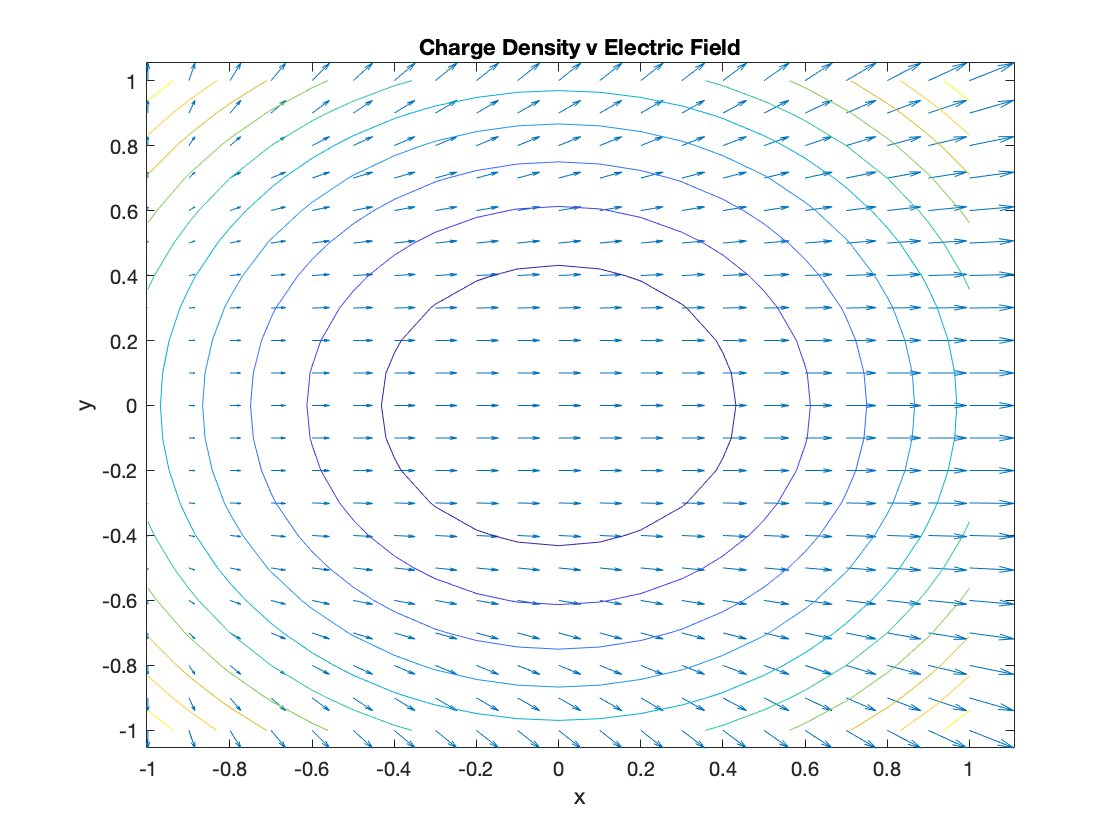

syms x y t
E = [(x^3+1) y^3];
%use of maxwells equations
epesilon0 = 8.85e-12;
chargedensity= epesilon0*divergence(E,[x y]);
%setting area to display on graph
v = [-1:0.1:1];
%creating 2d grid
[xcontour,ycontour] = meshgrid(v);
%substituting in meshgrid values into Electic Field Equation
    Ex = subs(E(1),x,xcontour);
    Ey = subs(E(2),y,ycontour);
%subbing in variables to create meshgrid
densityPlot = subs(chargedensity,{x,y},{xcontour,ycontour});
%plotting arrows
quiver(xcontour,ycontour,Ex,Ey)
hold on
%plotting charge density lines
contour(xcontour,ycontour,densityPlot)
title('Charge Density v Electric Field')
xlabel('x')
ylabel('y')

%calculation of force on particle
v0 = [5 0 0];
x = 1;
y = 1;
m = 9.10938356e-31;
%conversion of E field into 3space
E = [(x^3+1) y^3 0];
q = -1;
B = [2*x -2*y 0];
k = 8.99e9;
%use of Lorentz force equation
F = (q*k*[E + cross(v0,B)]/(9.10938356e-31))

F = 	1.0e+40 *

   -1.9738   -0.9869    9.8689
